# Notebook 6: Validation and Missing Physics

*Author:* Zachary del Rosario, Fall 2020

*Learning Objectives:* As a result of working through this notebook, you will learn:

- A productive mindset for model validation

- What it looks like when there are *missing physics* in our model

## Model Validation

In the previous notebook we studied some data from a scenario, and used it to fit a Susceptible, Infected, Recovered (SIR) model:

% Load the training data
tab_data_train = readtable("infected.csv", "Delimiter", ",")

tab_data_train = 6×2 table
    W    I 
    _    __

    1     2
    2     3
    3     5
    4     8
    5    11
    6    16


We fit an SIR model to those data, and used it to make a prediction.

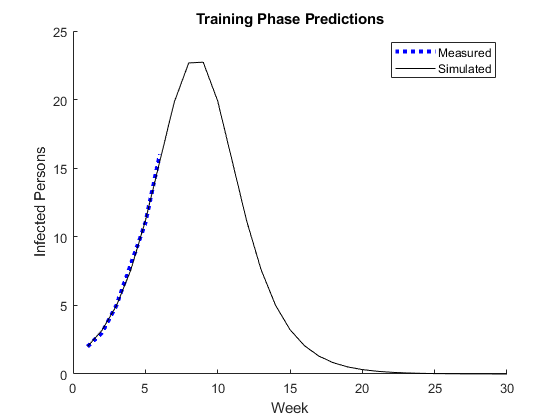

% NOTE: The following is my fitted model
beta = 1 / 90; % Infection rate (New / Susceptible / Infected / day)
gamma = 1 / 2; % Recovery rate (1 / day)
i_0 = 2;       % Initial count of infected persons

% Define initial state
s_0 = 100 - i_0;
r_0 = 0;

% Run simulation
[S_fit, I_fit, R_fit, W_fit] = sir_simulate(s_0, i_0, r_0, beta, gamma, 30);

% Plot the fitted simulation
figure(1); clf; hold on;
plot(tab_data_train.W, tab_data_train.I, 'b:', 'LineWidth', 3); label1 = "Measured";
plot(W_fit, I_fit, 'k-'); label2 = "Simulated";

xlabel("Week")
ylabel("Infected Persons")
legend({label1, label2})
title("Training Phase Predictions")

While the overlap of Measured and Simulated data is *encouraging*, we should maintain a healthy dose of skepticism towards these model results until we *validate* the model.

**Validation Steps:** To validate a physical model, we should follow a set of steps:

- *Clearly state* the purpose for which we want to use our model. This should include the scenario we are studying, and the questions we want to answer.

- Construct our model based on understanding of the physical phenomena at play.

- Use *training data* to fit the parameters in the model and determine if the model is *flexible* enough to represent the data.

- Use *validation data* to assess whether the model is *trustworthy* enough to support answering our questions.

The *validation data* should lie "outside" our training data, in order to test whether our is *trustworthy *enough to extrapolate outside what we've seen before. This is important for answering the questions we have about the flu: Remember we were interested in answering:

**Questions**

- When will this flu season be over?

- How many of the 100 total persons will fall ill with the flu?

The training phase results are encouraging, in that they indicate the model can fit behaviors we've seen before. But what about something we haven't seen before? To test if the model is valid for predicting results in the future, we need to check it against data not used in fitting to see if the model as-fit can predict future results. To that end, let's load some additional data to serve validation purposes.

% Load the validation data
tab_data_validate = readtable("wave1.csv", "Delimiter", ",")

tab_data_validate = 18×2 table
    W     I 
    __    __

     1     2
     2     3
     3     5
     4     8
     5    11
     6    16
     7    20
     8    23
     9    23
    10    20
    11    16
    12    12
    13     8
    14     6
    15     4
    16     3


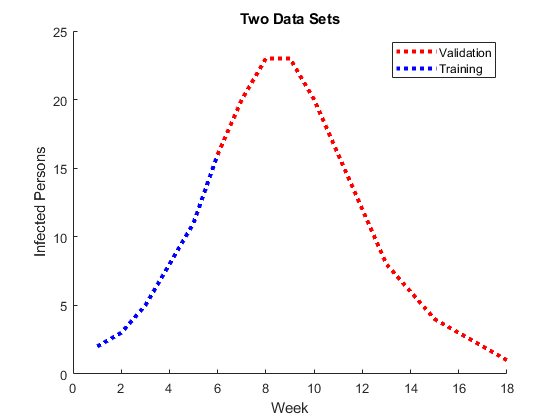


% Plot the training and validation data
figure(2); clf; hold on;
plot(tab_data_validate.W, tab_data_validate.I, 'r:', 'LineWidth', 3); label1 = "Validation";
plot(tab_data_train.W, tab_data_train.I, 'b:', 'LineWidth', 3); label2 = "Training";

xlabel("Week")
ylabel("Infected Persons")
legend({label1, label2})
title("Two Data Sets")

Notice that the validation data extends beyond the training data. It's important that we do not touch the validation data at all when fitting the model.

Now let's complete the validation exercise by comparing the model against the validation data.

**Exercise:** Create a plot of `tab_data_validate` against the simulation results `W_fit, I_fit`.

*Solution:*

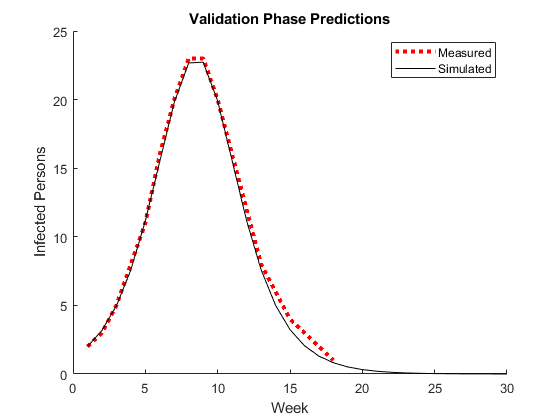

% NOTE: Solution code
figure(2); clf; hold on;
plot(tab_data_validate.W, tab_data_validate.I, 'r:', 'LineWidth', 3); label1 = "Measured";
plot(W_fit, I_fit, 'k-'); label2 = "Simulated";

xlabel("Week")
ylabel("Infected Persons")
legend({label1, label2})
title("Validation Phase Predictions")

We can see the agreement between simulation and validation data is not perfect. However, it's sufficiently good to answer our questions. These results indicate that our model is valid for predicting a few weeks into the future.

**Important Note: **It may seem circular that we're using data from "the future" (beyond Week 6) to validate the model. In real cases of model validation we will take *historical* data, split it into training and validation sets, and perform the same exercise. In that case, it's important to split the data in a way that matches the way you intend to use the model; for instance, if making predictions in the future, make sure your validation data contains information further forward in time than what's contained in your training data.

**A Productive Mindset:** When building a model, we should maintain a healty degree of skepticism towards our model. Remember, "All models are wrong, some are useful." *Validation* is a concrete way to put that skepticism into practice: By "stress testing" our model with data it hasn't seen before, we can get a sense of how well our model will perform when we use it to predict on scenarios we've not yet seen. This helps us build confidence---but not certainty---that our model will be useful.

Why should we have confidence but not certainty? Let's take a look at one way things can go wrong---when we're *missing some physics in our model.*

## Missing Physics

We've shown that the model is valid for the purpose of predicting a few weeks into the future. But what about predicting the next flu season? Let's load a second data set to see how well the model performs in that scenario:

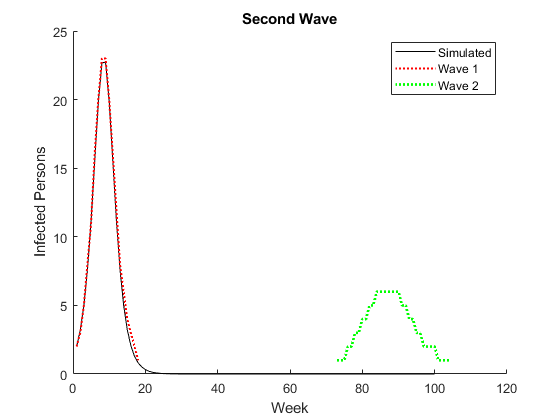

% Load the validation data
tab_data_wave2 = readtable("wave2.csv", "Delimiter", ",");

% Configure the simulation
beta = 1 / 90; % Infection rate (New / Susceptible / Infected / day)
gamma = 1 / 2; % Recovery rate (1 / day)
i_0 = 2;       % Initial count of infected persons
s_0 = 100 - i_0;
r_0 = 0;

% Run simulation
[S_long, I_long, R_long, W_long] = sir_simulate(s_0, i_0, r_0, beta, gamma, 100);

% Plot the fitted simulation
figure(3); clf; hold on;

plot(W_long, I_long, 'k-'); label1 = "Simulated";
plot(tab_data_validate.W, tab_data_validate.I, 'r:', 'LineWidth', 1.5); label2 = "Wave 1";
plot(tab_data_wave2.W, tab_data_wave2.I, 'g:', 'LineWidth', 2.0); label3 = "Wave 2";

xlabel("Week")
ylabel("Infected Persons")
legend({label1, label2, label3})
title("Second Wave")

The model is totally invalid for predicting the next flu season!

**Exercise:** Try tweaking the parameters under `tab_system_new` and `tab_state_new` to match this second wave phenomena. Convince yourself that it is not possible to represent both the first and second wave with the present model.

Let's think about why our present model can't represent this second wave. Remember the stock and flow diagram for this model:

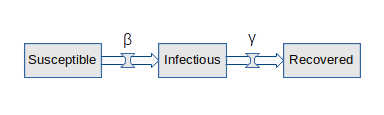

This stock and flow diagram has just two flows, Infections carry individuals from S to I, and Recoveries carry individuals from I to R. In this model *only Susceptible* *persons can become Infected*. 

**Exercise:** Answer the following questions:

- What *physical causes* could lead to a person getting re-infected with the flu? Name two or three possible causes. *Hint:* The US Centers for Disease for Disease Control and Prevention (CDC) publishes articles on [this topic](https://www.cdc.gov/flu/about/viruses/change.htm).

- How could we *represent* these physical causes in our model? What *additional flow* would you add to the model, and what physical mechanism would this represent?

*Solution:*

- Possible causes include genetic alterations to the flu virus (caused by antigenic shift and drift), or decay in an individual's immunity. Both mechanisms could lead to a person getting re-infected with the flu.

- We could represent this re-infection pathway as a flow from Recovered to Susceptible. Either of the mechanisms above could render a person susceptible, but there's still a chance they could avoid being exposed to the flu and avoid infection.